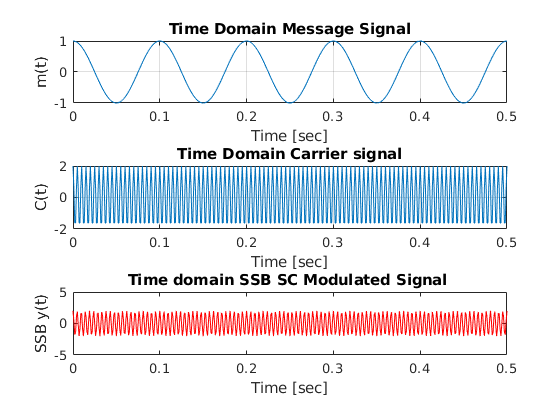

clc;
clear all;
close all;

A1=1;          % message signal Amplitude
Ac=2;          % carrier signal Amplitude
fm=10;         % message signal frequency taken (10 Hz here)
fc=20*fm;      % carrier freq taken 10 times message signal frequency (100 Hz)
mod=1;         % Modulation index we take 1

fs=100*fm;       % sampling freq 100 times that of message signal(1000 Hz)
Ts=1/fs;       % sampling time (0.001 sec)
t=0:Ts:5/fm;    % Generating the time vector for 5 periods of message signal (period =1/fm)

message= A1*cos(2*pi*fm*t);  % message signal frequency 10 Hz
carrier= Ac*cos(2*pi*fc*t);  % carrier signal Freq=200Hz
carrierpi= Ac*sin(2*pi*fc*t);  %Carrier signal shifted by pi/2 (cos becomes sin )for using with hilbert transform of message

figure;
subplot(311);
plot(t,message);
xlabel('Time [sec]');
ylabel('m(t)');
title('Time Domain Message Signal');
grid;

hold on;
subplot(312);
plot(t,carrier);
xlabel('Time [sec]');
ylabel('C(t)');
title('Time Domain Carrier signal');
grid;
hold on;

% Hilbert transform of baseband 
mh = imag(hilbert(message));  
  
% SSB with USB
modt = message.*carrier- mh.*carrierpi; 

subplot(313);
plot(t,modt,'r');
xlabel('Time [sec]');
ylabel('SSB y(t)');
title('Time domain SSB SC Modulated Signal ');

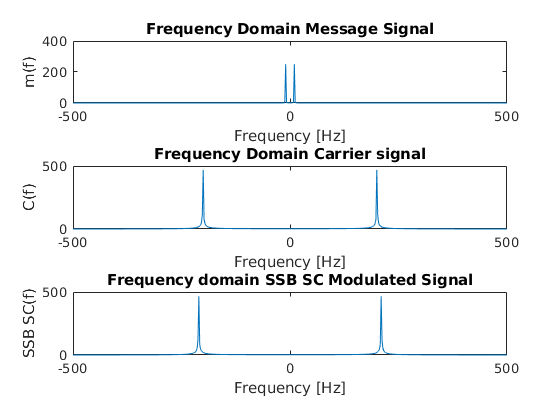


% Plotting the signals in frequency domain
modf=fftshift(fft(modt)); % fourier transform  of SSB SC modolated signal shifted for period -pi to pi
mf=fftshift(fft(message)); % fourier transform  of message signal shifted for period -pi to pi
cf=fftshift(fft(carrier)); % fourier transform  of carrier signal shifted for period -pi to pi
f=linspace(-fs/2,fs/2,length(t)); %generating the frequency vector
figure;
subplot(311);   %To plot frequencies of message,carrier , SSB SC modulated signal in same plot
plot(f,abs(mf));  %Plotting frequency response of message signal
xlabel('Frequency [Hz]');
ylabel('m(f)');
title('Frequency Domain Message Signal');

hold on;
subplot(312);
plot(f,abs(cf));  %Plotting frequency response of carrier signal
xlabel('Frequency [Hz]');
ylabel('C(f)');
title('Frequency Domain Carrier signal');
hold on;
subplot(313);
plot(f,abs(modf));  %Plotting frequency response of SSB SC molulated signal
xlabel('Frequency [Hz]');
ylabel('SSB SC(f)');
title('Frequency domain SSB SC Modulated Signal');

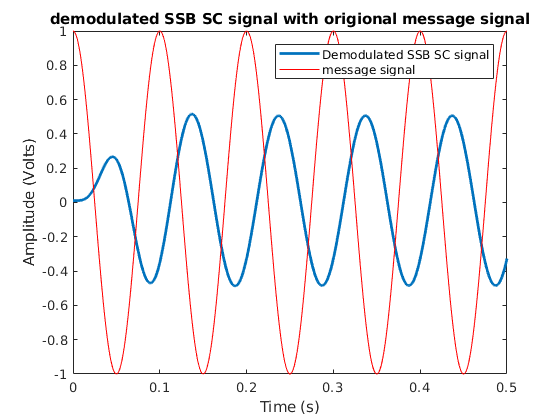


%Demodulation

% Step 1: Synchronous Demodulation using carrier
Vc = modt.*carrier;

% Step 2: Low Pass RC Filter

[b,a] = butter(5,fm*3/fs);  %We can also use Butterworth Filter
ym_rec = filter(b,a,Vc); % filtering the demodulated signal
ym_rec = ym_rec - mean(ym_rec); %To reduce error
ym_rec = ym_rec/Ac^2;   

figure;
plot(t, ym_rec,'LineWidth',2);  %Plotting the demodulated message signal
hold on;
plot(t,message,'r');
title('demodulated SSB SC signal with origional message signal');
legend("Demodulated SSB SC signal","message signal");
xlabel('Time (s)');
ylabel('Amplitude (Volts)');

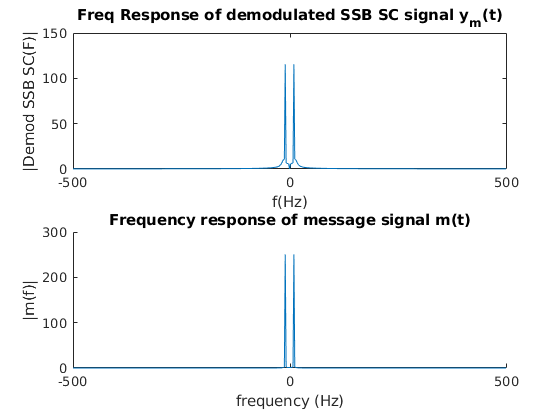


Nf=length(ym_rec); %To take fft of Nf point
ym_rec_fft = fftshift(fft(ym_rec,Nf));  % Frequency Response of retrieved message signal
f = (-Nf/2:1:Nf/2-1)*fs/Nf;

figure;
subplot(211);
plot(f,abs(ym_rec_fft));
hold on;
title('Freq Response of demodulated SSB SC signal y_m(t)');
xlabel('f(Hz)');
ylabel('|Demod SSB SC(F)|');

subplot(212);
hold on; 
plot(f,abs(mf));
xlabel("frequency (Hz)");
ylabel("|m(f)|");
title("Frequency response of message signal m(t)");